## S18C Barcode Detection Documentation

Jean-Nicola Blanchet, August 2020

The purpose of this document is to expose each step of the proposed solution to the barcode detection problem. Detection is a computer vision problem defined as the search of the location of an object of a specific class in an image. In this instance, the class of the object of interest is a S18C barcode.

Future improvements to this solution include fine tuning of the parameters through non-linear or evolutionnaly search on real-world data. Such data is not available at this time. 

### Loading the a sample Image from the synthetic dataset

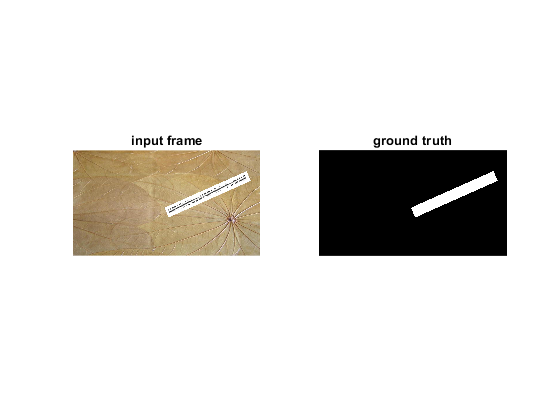

clear
clc
close all

trainingSample = 2;
output = sprintf('data/trainning2/code%05d.jpg',trainingSample);
outputgt = sprintf('data/trainning2/gt%05d.jpg',trainingSample);
f = im2double(imread(output));
gt = im2double(imread(outputgt));

figure(1)
subplot(1,2,1), imshow(f), title('input frame');    
subplot(1,2,2), imshow(gt), title('ground truth');    

### Preprocessing

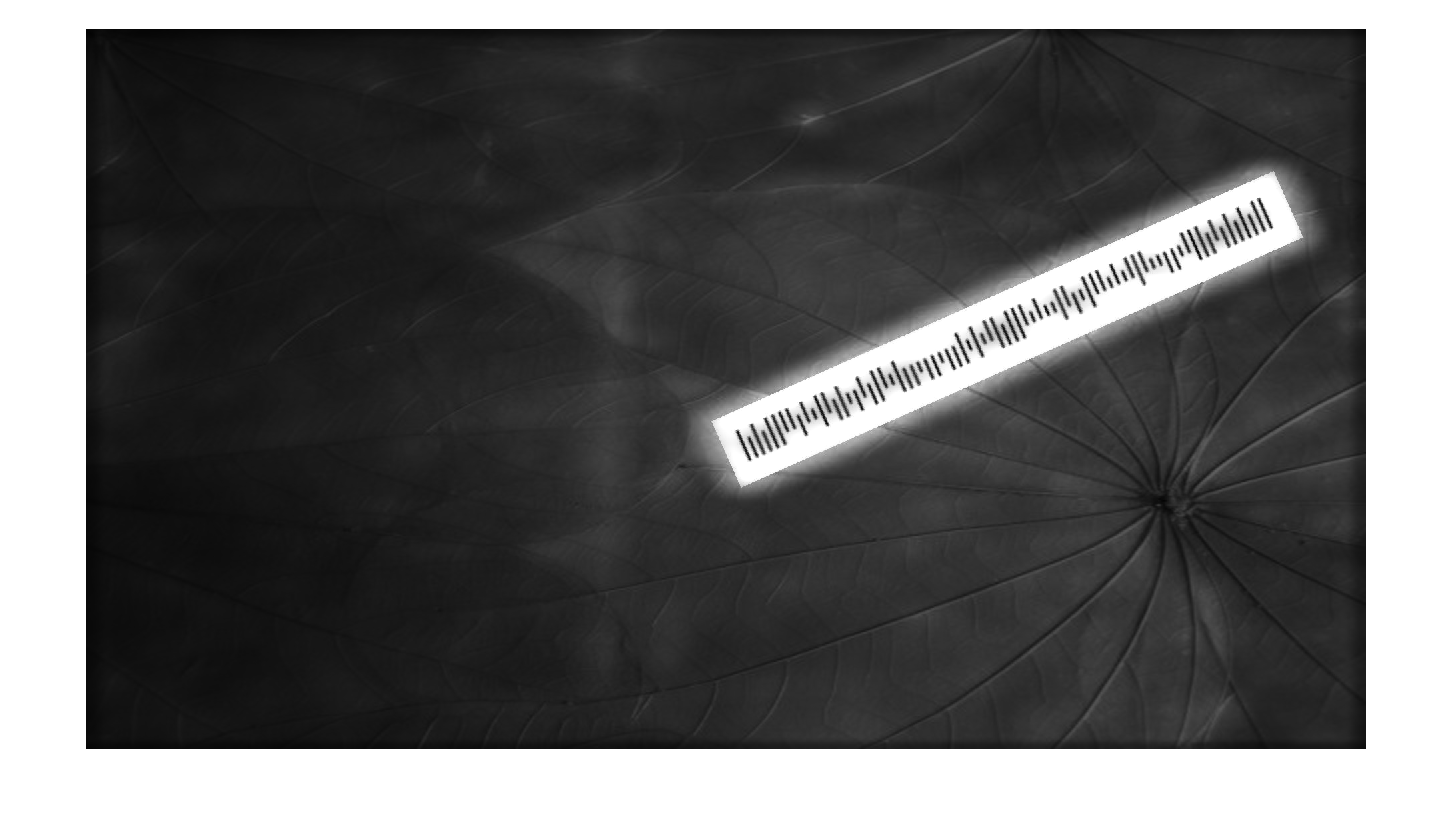

f = rgb2gray(f);

candidatefilter = imresize(imresize(imresize(f,[400,400]),[200,200]),[100,100]);
candidatefilter = imdilate(candidatefilter,ones(3));
candidatefilter = candidatefilter.^3;
candidatefilter = imfilter(candidatefilter,ones(3)/9);
f = f .* imresize(candidatefilter,size(f));
figure, imshow(f);

There are 2 preprocessing steps. 

- Firstly the image is converted to gray scale.

- Secondly, a dilation filter is used to eliminate parts of the image that do not contain a large bright area. From the S18C specification, we know the barcode shall be padded with a white border. To improve dilation performance, the image is rescaled. The rescale process is done in 3 steps to preserve detail.

### Feature extraction

BLOCK_SIZE = 30;
[B,O,theta,mag] = extractBarCodeFeatures(f,BLOCK_SIZE);

Features are extracted in a grid with cells of size 30x30. We found this scale to generalize well for various practical sizes of bar codes. Because feature extraction is the only step that is performed for every pixel of the image, it is important to use highly efficient per-pixel operations. We also chose features that will be useful later on for post-processing alignment.

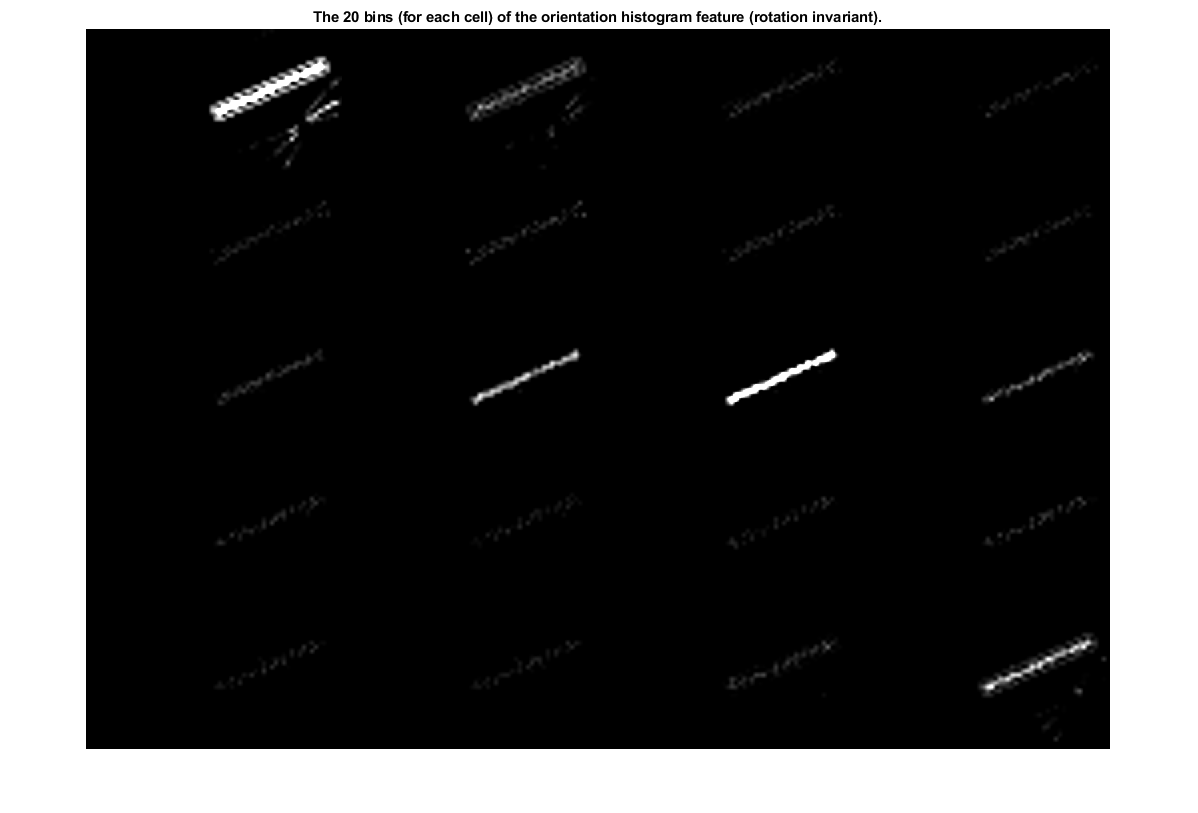

figure
montage(B*3) % multiplication for visualization only
title('The 20 bins (for each cell) of the orientation histogram feature (rotation invariant).')

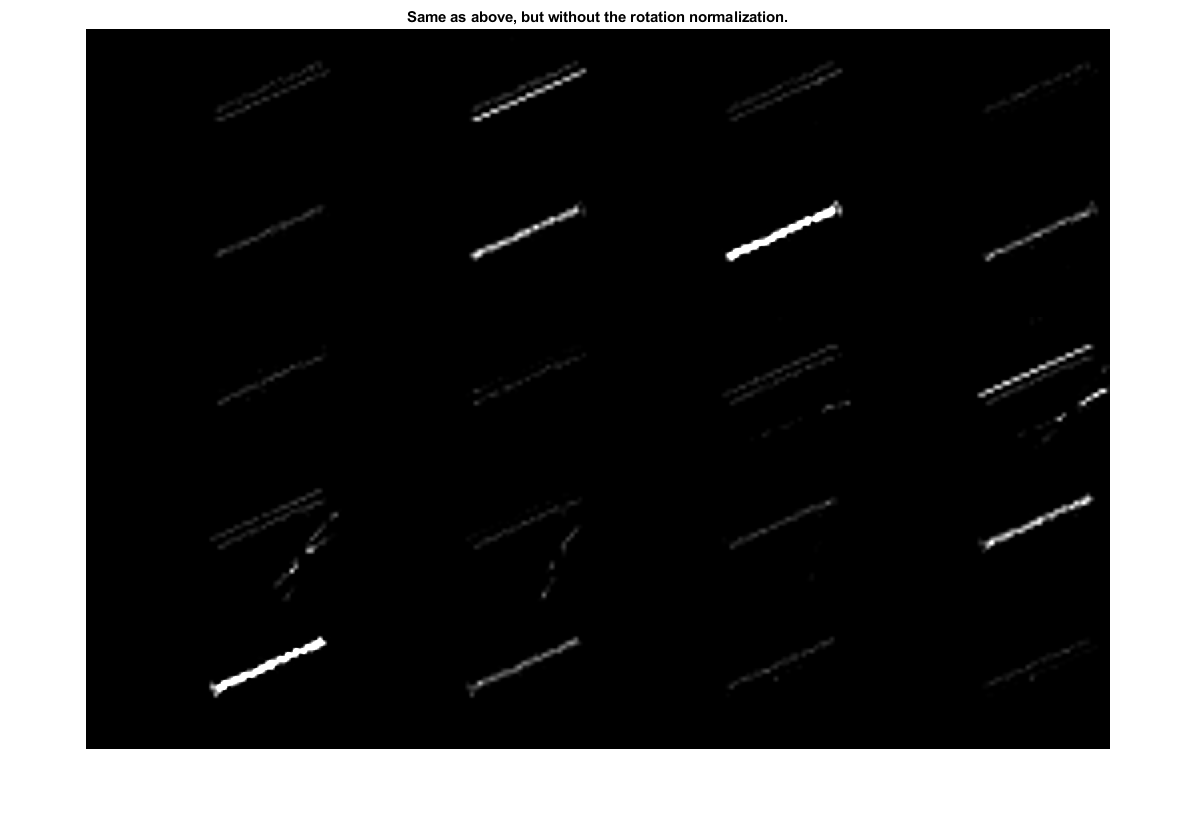

figure
montage(O*3)
title('Same as above, but without the rotation normalization.')

The feature extraction process goes as follow:

- A sobel filter is applied to extract the per-pixel gradient vector.

- The fast magnitude approximation of the Sobel filter is computed

- The gradient orientation is computed using atan.

- The orientation is quantized into 20 bins.

- The quantized orientations are aggregated (per cell) into a magnitude-weighted histogram.

- The resulting 20 feature vectors (one per cell) are normalized by dividing by the maximum value across all bins and all cells. This normalization avoids boosting the features of a plain or noisy uniteresting image.

- Features for the edges of the image are set to 0. It is assumed the bar code will not be located along the edges of the image.

- The resulting feature matrix is called O, and is used later on for filtering.

- The feature matrix O is the dephased to bring the maximum bin at the first position. This will allow rotation invariant detection. The phase-corrected feature matrix is called B.

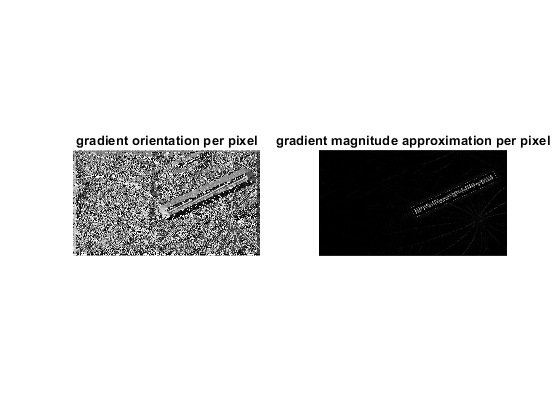

figure, subplot(1,2,1),imshow(theta,[]), title('gradient orientation per pixel')
subplot(1,2,2),imshow(mag,[]), title('gradient magnitude approximation per pixel')

### Loading the localization model

M = [    0.1727    0.2663   -0.3798    0.1060   -0.1066    0.0781    0.0702    0.0419   -0.3978   -0.0573    0.5503   -0.2915   -0.4312    0.2244   -0.0441    0.0782   -0.1100   -0.1528   -0.0411    0.1875]';

A weak localization model is used to quickly and efficiently identify potential regions of interest. The model.mat file contains a regression matrix M. At the moment, the model uses simple linear regression with an activation function for classification. Linear regression has the following advantages:

- Very low computational cost

- Most implementation of matrix multiplication leverage SIMD hardware instructions on both CPU and GPU.

- Easy to retrain

- Low capacity (lower chances of overfitting, better chances of generalizing)

- Acheives the desired goal of efficient weak classification.


$$S=\textrm{sign}\left(M^T B-T\;\right)$$


where

- S=1 for a valid cell and -1 for a background cell

- B is the extracted barcode feature vector (described above)

- and T is the bias that controls sensitity

Through optimization on synthetic data, we found that a good adaptive biais candidate can be obtained by finding the 93th percentile score $M^T B$ across the image. This enables barcode localization is highly diverse conditions, including blurry or noisy images.

### Apply the localization model

Using the model described above, each cell is classified into a binary value, where true signals that the cell may contain a barcode.

% rescale the ground truth so we can track our results later
gt = imread(outputgt)>0;
isBarcodeBlock = blockproc(gt,[BLOCK_SIZE BLOCK_SIZE],@(x) max(x.data(:)));
[bx,by] = size(isBarcodeBlock);

% reshape the features for matrix multiplication
B = reshape(B,size(B,1)*size(B,2),size(B,3));
O = reshape(O,size(O,1)*size(O,2),size(O,3));

% classify 
score = B * M; % eval
valid = score > prctile(score(:),93); % from optimization process

The following figure shows the cells that are candidates for pieces of S18C barcodes:

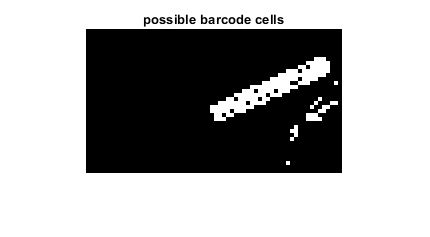

figure, imshow(imresize(reshape(valid,bx,by),4,'nearest')), title('possible barcode cells')

### Filter barcode candidates by orientation

The 10 strongest barcode-lie cells vote on the orientation.

TODO: use a number of bins that splits evenly at 180°, and fold the feature vector in 2 (or just use correlation or something else)

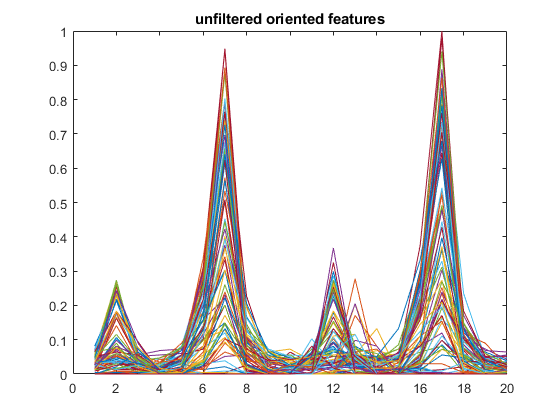

figure, plot(O(valid,:)'), title('unfiltered oriented features');

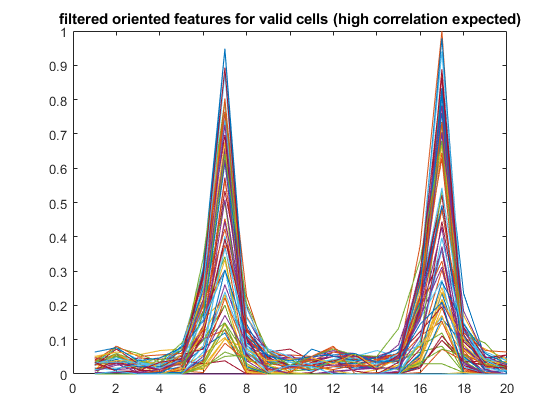


% have the strongest 10 vote
N = size(O,2)/2;
[~,direction] = max(O(valid,1:N) + O(valid,N+1:end),[],2);
valid_scores = score(valid);
[~,top] = sort(valid_scores,'descend');
T_strongest_scores = valid_scores(top(10));
consensus = mode(direction(valid_scores > T_strongest_scores)); % TODO: need to scan all promising angles (for multiple codes)
valid(valid) = direction == consensus;
       
figure, plot(O(valid,:)'), title('filtered oriented features for valid cells (high correlation expected)');

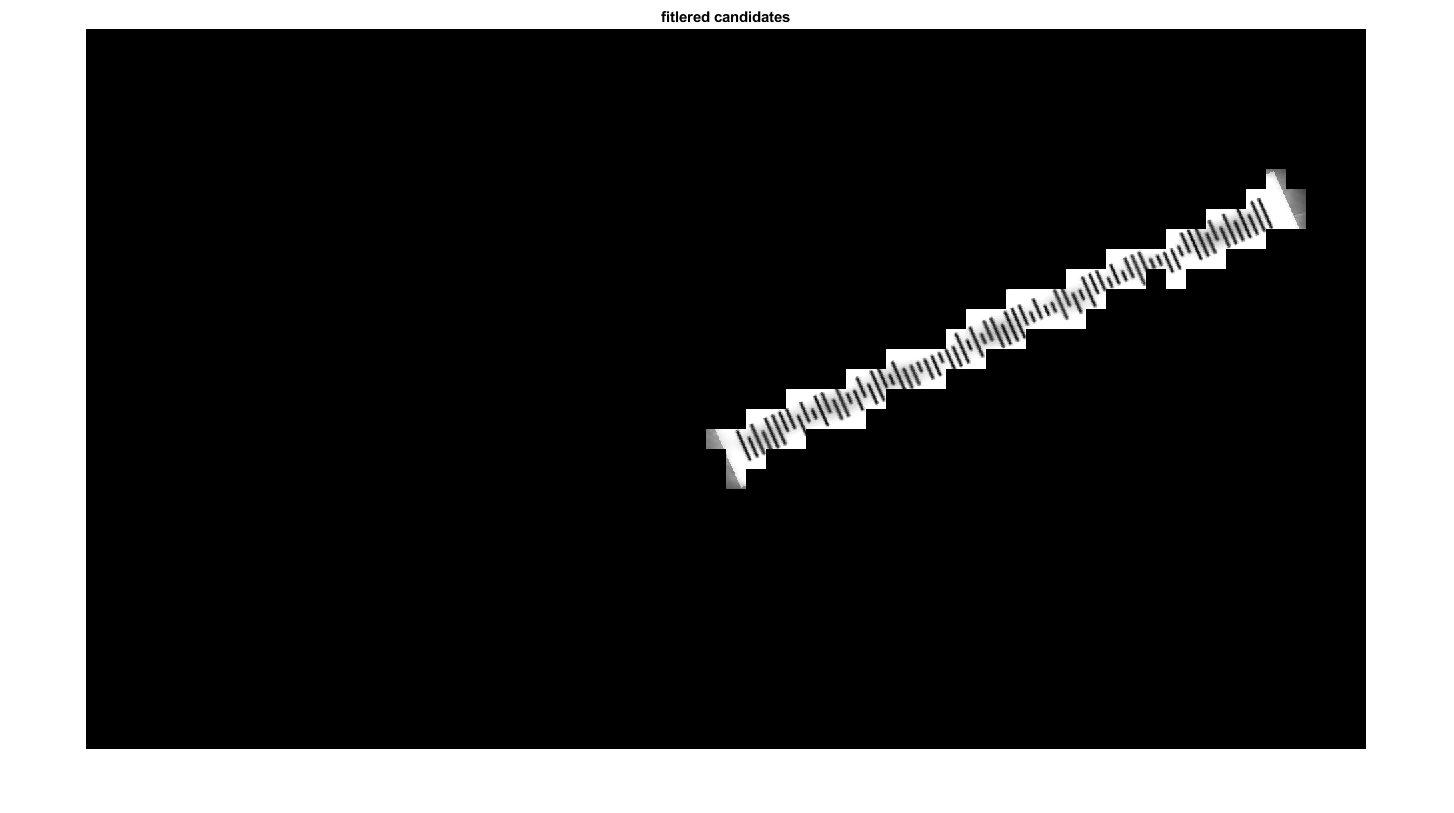

    
% analyse the result
valid = reshape(valid,bx,by);
valid_ = double(imresize(valid, size(f,[1 2]),'nearest'));
score = reshape(score,bx,by);

figure
imshow(valid_ .* f)
title('fitlered candidates')

### Region Filtering and Refinement

Post-processing dilation is applied to eliminate ambiguity from weakly connected parts of the barcode (e.g. due to image noise).

Connected component is applied to take a closer look at each identified region. Two features are extracted (1) area, (2) list of pixels. Note that very similar behavior can be obtained using OpenCV's contour features.

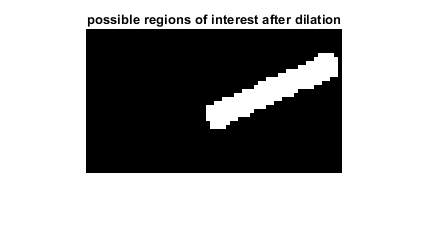

    MIN_BAR_CODES = 57; % if less, don't bother
    DILATION_SIZE = floor(2 + numel(valid) / 1000); % larger for larger images
    valid_d = imdilate(valid,true(DILATION_SIZE));
    figure, imshow(imresize(valid_d,4,'nearest')), title('possible regions of interest after dilation');


    MIN_AREA_EXPECTED = 0.04 * numel(valid_d); % 4% of area of frame
    barcodeCandidatesRegions = regionprops(valid_d,'area','PixelIdxList');


For each identified regions, a series of weak tests based on the S18C specification as well as hand crafted heuristics aim to further refine the region:

- Barcodes are expected to cover at least 4% of the image

- Bars in the barcode should have an eccentricity of 80%.

- Every bar in the barcode should be of similar size.

- Valid bars should all share the same orientation.

- Bars should be aligned vertically (similar Y coordinate)

- Bars should be spaced evenly vertically (structured X coordinate)

- To be considered for parsing, at least 40 bars should be located correctly. (the remaining bars can be recovered at the parsing stage).

176 regions after initial detection.


102 regions after Eccentricity filtering.


75 regions after Area filtering.


75 regions after vertial grouping filter.


75 regions after horizontal grouping filter.


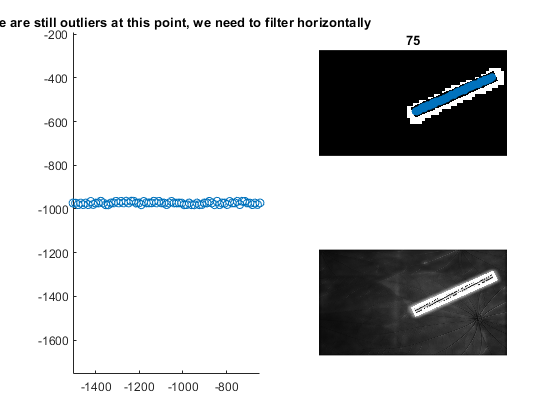

    debugfound = false;
    for id = 1:numel(barcodeCandidatesRegions)
        if barcodeCandidatesRegions(id).Area > MIN_AREA_EXPECTED
            %focus on that region
            valid_d(:) = false;
            valid_d(barcodeCandidatesRegions(id).PixelIdxList) = true;
            valid_d_large = imresize(valid_d,size(theta),'nearest');
            
            barthresh = graythresh(f(valid_d_large));
            barcandidates = f < barthresh & valid_d_large;
            
            % find bars
            stats = regionprops(barcandidates,'Centroid','Orientation','Area','Eccentricity','PixelIdxList');
            fprintf('%d regions after initial detection.\n',numel(stats));
            if numel(stats) < MIN_BAR_CODES
                continue;
            end
            % eliminate things that aren't bars
            stats([stats.Eccentricity] < 0.8) = [];
            fprintf('%d regions after Eccentricity filtering.\n',numel(stats));
            % eliminate huge regions
            A = [stats.Area];
            regular_bar_size_estimate = median(A);
            stats(A > 2.5 * regular_bar_size_estimate | A < regular_bar_size_estimate / 4) = [];
            fprintf('%d regions after Area filtering.\n',numel(stats));
            % get centers
            centers = reshape([stats.Centroid],2,[]);
            % get orientation
            orientation = median([stats.Orientation]);
            
            rot = @(angle) [ cosd(angle), -sind(angle); sind(angle), cosd(angle)];
            rotated_centers = rot(90-orientation)' * centers;
            
            % keep only the ones closely related vertically
            med = median(rotated_centers(2,:));
            ditrib = abs(rotated_centers(2,:) - med);
            tolerance = std(ditrib(ditrib < mean(ditrib) * 2.5))*3;
            remove = ditrib > tolerance;
            stats(remove) = [];
            fprintf('%d regions after vertial grouping filter.\n',numel(stats));
            
            % remove the ones that are far left or far right
            rotated_centers = rot(90-orientation)' * reshape([stats.Centroid],2,[]);
            [pos,ids] = sort(rotated_centers(1,:));
            skip = min([abs(pos(1:end-1) - pos(2:end)) Inf],[Inf abs(pos(2:end) - pos(1:end-1))]);
            tolerance = mean(skip);
            remove = skip > (tolerance * 1.5);
            stats(ids(remove)) = [];
            fprintf('%d regions after horizontal grouping filter.\n',numel(stats));
            
            if numel(stats) <= 40% this is for debug only, find codes that are "kind of" well detected
                continue;
            end
            
            %     assert(numel(stats) == 57 || numel(stats) == 75,'did not filter out junk properly');
            
            % make sure we're good so far
            figure(5)
            centers = reshape([stats.Centroid],2,[]); % for display only
            rotated_centers = rot(90-orientation)' * centers;
            subplot(1,2,1);
            scatter(rotated_centers(1,:),rotated_centers(2,:))
            axis('equal')
            title('if there are still outliers at this point, we need to filter horizontally');
            subplot(2,2,2);
            imshow(f < barthresh & valid_d_large)
            hold on
            scatter(centers(1,:),centers(2,:),'filled')
            hold off
            title(num2str(numel(stats)));
            subplot(2,2,4);
            imshow(f)
            
            debugfound = true;
        end
    end

    assert(debugfound,'couldn''t locate code');